# Zad 1

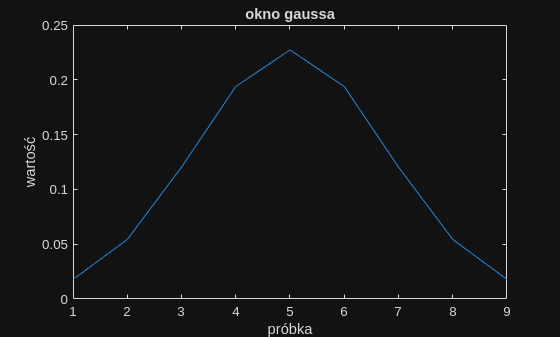

noiseSig=load("noiseSig.dat");

sigma = 1.33;
n = 9;

t = linspace(-3*sigma, 3*sigma, n);
gauss_filter = gausswin(n, n/(3*sigma));
gauss_filter = gauss_filter/sum(gauss_filter);
figure
plot(gauss_filter)
xlabel("próbka")
ylabel("wartość")
title("okno gaussa")

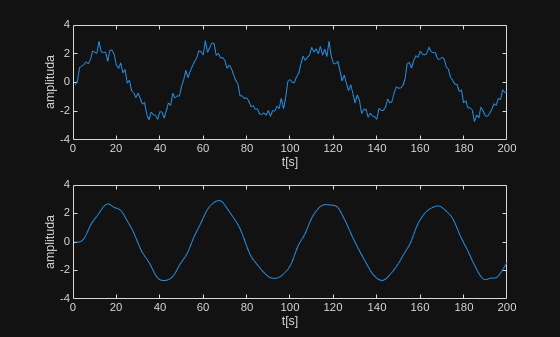

sig_conv =conv(gauss_filter,noiseSig);
scaling_factor = max(abs(noiseSig)) / max(abs(sig_conv));
sig_conv = sig_conv * scaling_factor;

figure 
subplot(2,1,1)
plot(noiseSig)
xlabel("t[s]")
ylabel("amplituda")

subplot(2,1,2)
plot(sig_conv)
xlim([0 200])
ylabel("amplituda")
xlabel("t[s]")

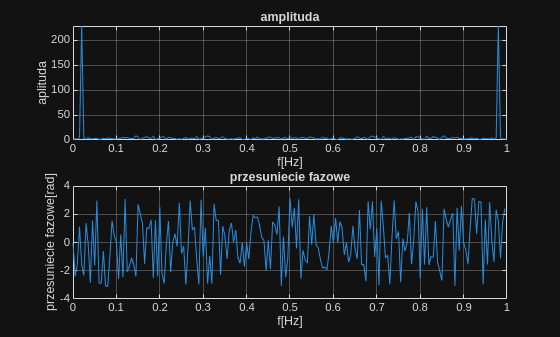

plotspectrum(noiseSig,1);

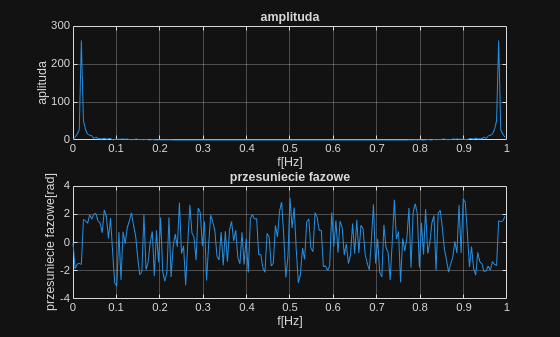

plotspectrum(sig_conv,1);

# Zad 2 

n = 100000;  
poly1 = rand(1, n) - 0.5;  
poly2 = rand(1, n) - 0.5;

tic;
res_poly_ftt=fpm(poly1,poly2);
time_fft=toc

time_fft = 0.1182

tic;
res_poly_conv = conv(poly1,poly2);
time_conv = toc

time_conv = 0.2954

diff=max(res_poly_conv-res_poly_ftt)

diff = 2.4727e-12

disp(diff<10^-6)%wyswietla sie 1(True) wiec roznica nie jest wieksza od 10^-6

   1



# Zad 3

% nie ma pliku filtr xd 
